# Simple Linear Regression

This example shows how to perform simple linear regression using the `accidents` dataset. The example also shows you how to calculate the coefficient of determination $R^2$ to evaluate the regressions. The `accidents` dataset contains data for fatal traffic accidents in U.S. states. 

Linear regression models the relation between a dependent, or response, variable $y$ and one or more independent, or predictor, variables $x_1, ..., x_n$. Simple linear regression considers only one independent variable using the relation


$$y = \beta_0 + \beta_1x + \epsilon,$$


where $\beta_0$ is the y-intercept, $\beta_1$ is the slope (or regression coefficient), and $\epsilon$ is the error term.

Start with a set of $n$ observed values of $x$ and $y$ given by $(x_1,y_1)$, $(x_2,y_2)$, ..., $(x_n,y_n)$. Using the simple linear regression relation, these values form a system of linear equations. Represent these equations in matrix form as


$$\left[\matrix{y_{1}\cr y_{2}\cr \vdots \cr y_{n}\cr}\right] =
\left[\matrix{1 & x_{1}\cr 1 & x_{2}\cr \vdots & \vdots\cr 1 & x_{n}}\right]
\left[ \matrix{\beta_{0} \cr \beta_{1}}\right].$$


Let


$$Y = \left[\matrix{y_{1}\cr y_{2}\cr \vdots \cr y_{n}\cr}\right], 
X = \left[\matrix{1 & x_{1}\cr 1 & x_{2}\cr \vdots & \vdots\cr 1 &
x_{n}}\right], B = \left[ \matrix{\beta_{0} \cr \beta_{1}}\right].$$


The relation is now $Y = XB$.

In MATLAB, you can find $B$ using the [mldivide](docid:matlab_ref.btg5qam) operator as `B = X\Y`.

From the dataset `accidents`, load accident data in `y` and state population data in `x`. Find the linear regression relation $y = \beta_1x$ between the accidents in a state and the population of a state using the `\` operator. The `\` operator performs a least-squares regression. 

load accidents
x = hwydata(:,14); %Population of states
y = hwydata(:,4); %Accidents per state
format long
b1 = x\y

b1 =      1.372716735564871e-04


`b1` is the slope or regression coefficient. The linear relation is $y = \beta_1x = 0.0001372x$.

Calculate the accidents per state `yCalc` from `x` using the relation. Visualize the regression by plotting the actual values `y` and the calculated values `yCalc`.

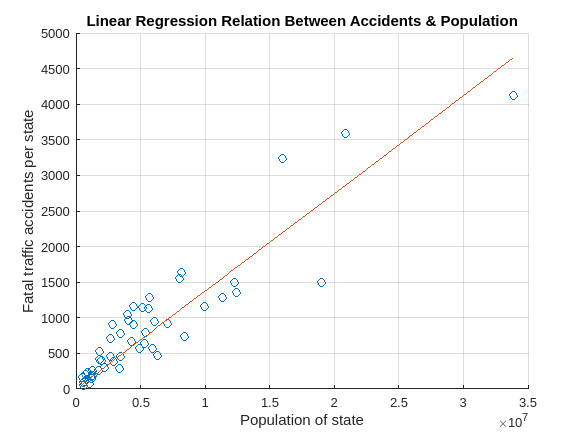

yCalc1 = b1*x;
scatter(x,y)
hold on
plot(x,yCalc1)
xlabel('Population of state')
ylabel('Fatal traffic accidents per state')
title('Linear Regression Relation Between Accidents & Population')
grid on

Improve the fit by including a y-intercept $\beta_0$ in your model as $y = \beta_0 + \beta_1x$. Calculate $\beta_0$ by padding `x` with a column of ones and using the `\` operator. 

X = [ones(length(x),1) x];
b = X\y

b = 1.0e+02 *

   1.427120171726538
   0.000001256394274


This result represents the relation $y = \beta_0 + \beta_1x = 142.7120 + 0.0001256x$.

Visualize the relation by plotting it on the same figure.

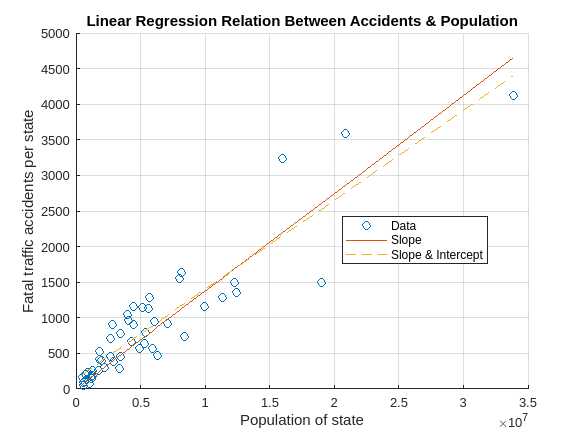

yCalc2 = X*b;
plot(x,yCalc2,'--')
legend('Data','Slope','Slope & Intercept','Location','best');

From the figure, the two fits look similar. One method to find the better fit is to calculate the coefficient of determination, $R^2$. $R^2$ is one measure of how well a model can predict the data, and falls between $0$ and $1$. The higher the value of $R^2$, the better the model is at predicting the data.

Where $\hat{y}$ represents the calculated values of $y$ and $\bar{y}$ is the mean of $y$, $R^2$ is defined as


$$ R^2 = 1 - \frac{\sum\limits_{i=1}^n \left(y_i - \hat{y}_i\right)^2}{\sum\limits_{i=1}^n \left(y_i - \bar{y}\right)^2}.$$


Find the better fit of the two fits by comparing values of $R^2$. As the $R^2$ values show, the second fit that includes a y-intercept is better.

Rsq1 = 1 - sum((y - yCalc1).^2)/sum((y - mean(y)).^2)

Rsq1 =    0.822235650485566


Rsq2 = 1 - sum((y - yCalc2).^2)/sum((y - mean(y)).^2)

Rsq2 =    0.838210531103428


*Copyright 2015 The MathWorks, Inc.*